file_path1 = 'C:\Users\gajapathy.s\Desktop\gps\occludedRTK.bag';
file_path2 = 'C:\Users\gajapathy.s\Desktop\gps\openRTK.bag';




 alt(file_path1,file_path2)

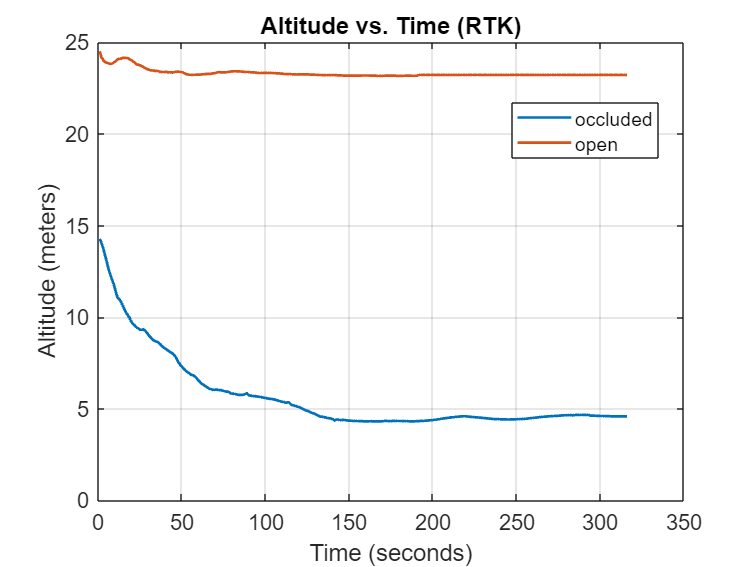

hold off

legend("Position", [0.67679,0.72262,0.19464,0.096429])

scatter_plot_error(file_path1,file_path2)

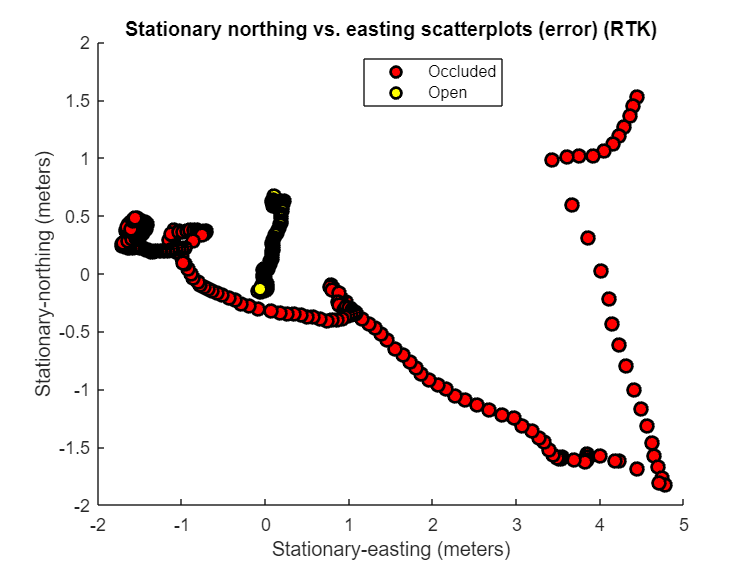

hold off

legend("Position", [0.48267,0.81433,0.18214,0.082143])

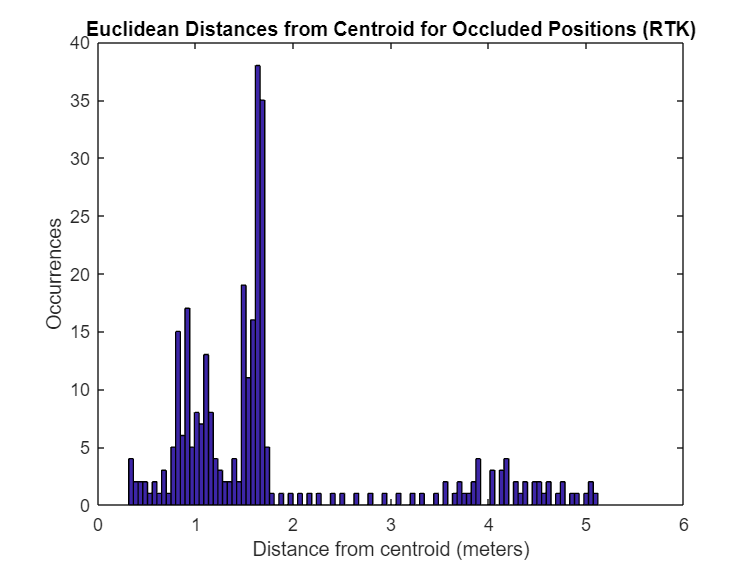

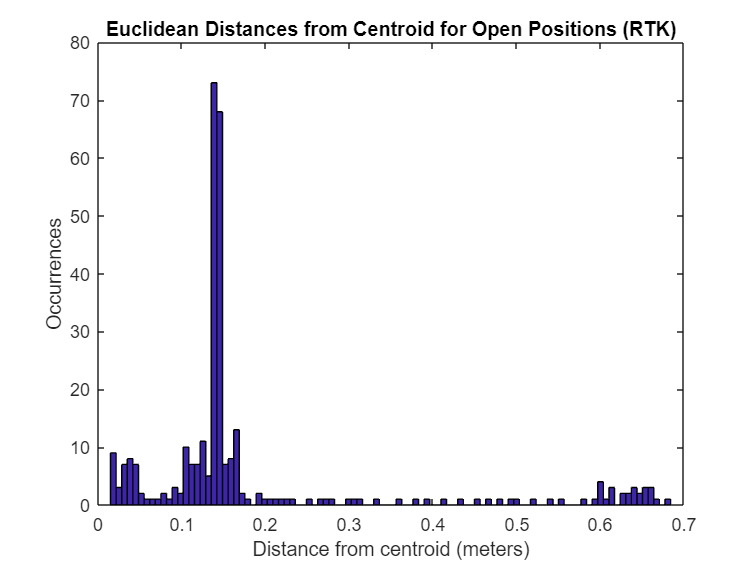









 Euclidean_dis(file_path1,file_path2)















[lat,long,Alt,UtmE,UtmN,delta_time,UE,UN,H]= extract_bag(file_path1);
 polar(UE,UN)

standard_deviation_easting = 2.0127

standard_deviation_northing = 0.6464

DRMS = 2.1140

CEP = 1.5279

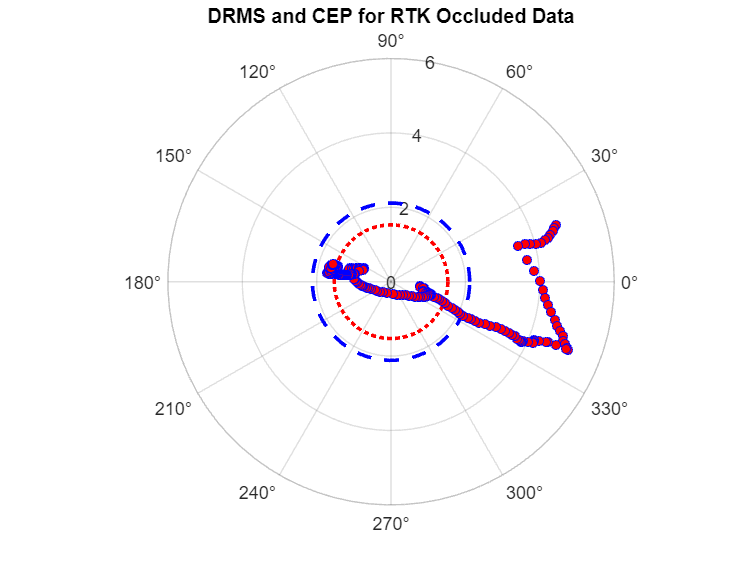

title('DRMS and CEP for RTK Occluded Data')


 [lat,long,Alt,UtmE,UtmN,delta_time,UE,UN,H]= extract_bag(file_path2);
 polar(UE,UN)

standard_deviation_easting = 0.0766

standard_deviation_northing = 0.2332

DRMS = 0.2455

CEP = 0.1875

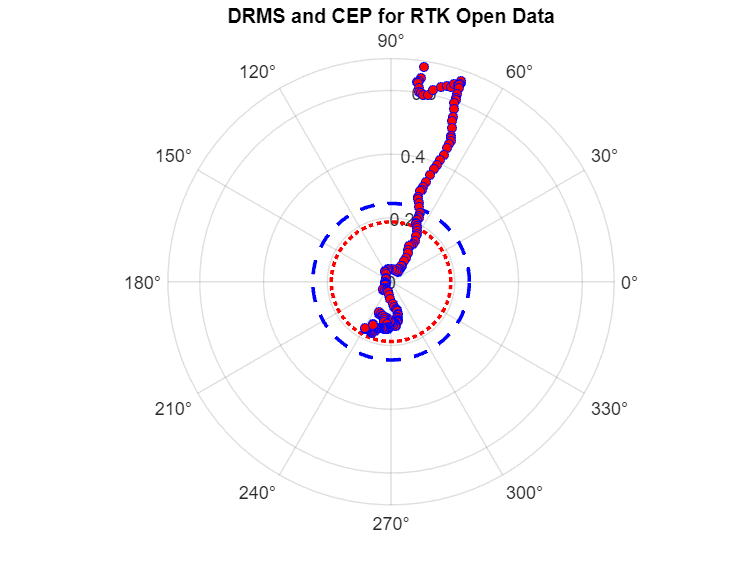

title('DRMS and CEP for RTK Open Data')

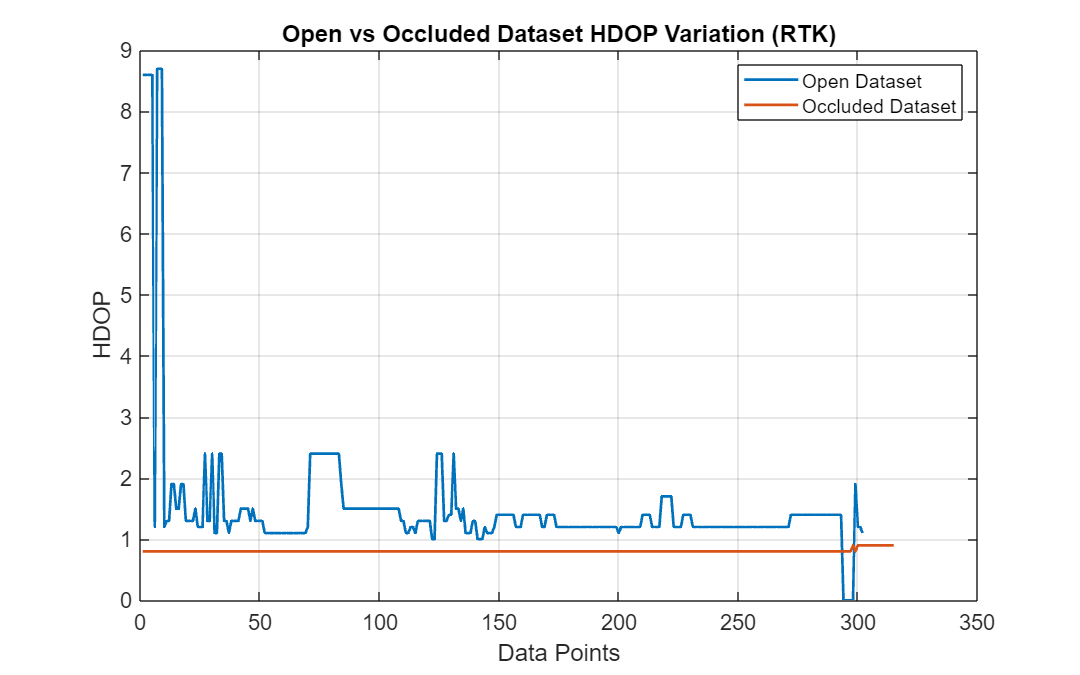





[lat1, long1, Alt1, UtmE1, UtmN1, delta_time1, UE1, UN1, H1] = extract_bag(file_path1);


[lat2, long2, Alt2, UtmE2, UtmN2, delta_time2, UE2, UN2, H2] = extract_bag(file_path2);


plot(H1, 'LineWidth', 1.5); 
hold on;


plot(H2, 'LineWidth', 1.5); 

hold off;

xlabel('Data Points');
ylabel('HDOP');
title('Open vs Occluded Dataset HDOP Variation (RTK)');


legend('Open Dataset', 'Occluded Dataset');


grid on; 
box on; 
set(gca, 'FontSize', 12);

set(gcf, 'Position', [100, 100, 800, 500]); 

function[]=polar(UE,UN)
    positions = [UE; UN];
    centroid = mean(positions, 2);
    diff = positions - centroid;

    standard_deviation_easting = sqrt(sum(diff(1,:).^2) / size(diff, 2))
    standard_deviation_northing = sqrt(sum(diff(2,:).^2) / size(diff, 2))

    DRMS = sqrt(standard_deviation_northing^2 + standard_deviation_easting^2)
    CEP = 0.62 * standard_deviation_northing + 0.56 * standard_deviation_easting

    % Plot DRMS circle
    theta = linspace(0, 2*pi, 100); 
    x_DRMS = DRMS * cos(theta);
    y_DRMS = DRMS * sin(theta);
    polarplot(theta, DRMS * ones(size(theta)), 'b--', 'LineWidth', 2);
  
hold on
    % Plot CEP circle
    x_CEP = CEP * cos(theta);
    y_CEP = CEP * sin(theta);
    polarplot(theta, CEP * ones(size(theta)), 'r:', 'LineWidth', 2);

for i = 1:size(diff, 2)
        polarplot(atan2(diff(2,i), diff(1,i)), norm(diff(:,i)), 'bo', 'MarkerSize', 5, 'MarkerFaceColor', 'r');
    end


hold off
end



function []= alt(file_path1,file_path2)

[lat,long,Alt,UtmE,UtmN,delta_time,UE,UN,H]= extract_bag(file_path1);
d1=delta_time;
a1=Alt;
 [lat,long,Alt,UtmE,UtmN,delta_time,UE,UN,H]= extract_bag(file_path2);
d2=delta_time;
a2=Alt;
if d1>d2
    delta_time=d2;
else if d2>d1
      delta_time=d1;
end

end
 altitude_(a1,delta_time,'r');
 hold on

 altitude_(a2,delta_time,'b');

function[]= altitude_(Alt,delta_time,c)

t = 1:1:delta_time;

 t = linspace(min(t), max(t), length(Alt));


 plot(t, Alt, 'MarkerFaceColor', c, 'LineWidth', 1.5);
 
% scatter(t, Alt, 'Marker', 'o', 'MarkerEdgeColor', 'k', 'MarkerFaceColor', c, 'SizeData', 100, 'LineWidth', 1.5, 'DisplayName', 'Data Points');

xlabel('Time (seconds)');
ylabel('Altitude (meters)');
title('Altitude vs. Time (RTK)');
legend("occluded","open")

grid on;

set(gca, 'FontName', 'Arial', 'FontSize', 12);
set(gcf, 'Color', 'w'); 

end
end




function []= scatter_plot_error(file_path1,file_path2)

 [lat,long,Alt,UtmE,UtmN,delta_time,UE,UN,H]= extract_bag(file_path1);
 scatterplot(UE,UN,'r');
 CutmE=mean(UE);
CutmN=mean(UN);



%  hold on
% % plot(CutmN, CutmE, 'r*', 'MarkerSize', 25)
%  hold off

 hold on
 [lat,long,Alt,UtmE,UtmN,delta_time,UE,UN,H]= extract_bag(file_path2);

 
 scatterplot(UE,UN,'y');
 CutmE=mean(UE);
CutmN=mean(UN);





%  hold on
% % plot(CutmN, CutmE, 'b*', 'MarkerSize', 25)
%  hold off

xlabel('Stationary-easting (meters)');
ylabel('Stationary-northing (meters)');
title('Stationary northing vs. easting scatterplots (error) (RTK)');
legend('Occluded','Occluded Centroid','Open','Open Centroid')
legend("Occluded","Open")

function []=scatterplot(UE,UN,c)
CutmE=mean(UE);
CutmN=mean(UN);

Stationary_northing=UE-CutmE;
% total_offset_northing=sum(Stationary_northing);

Stationary_easting=UN-CutmN;
% total_offset_northing=sum(Stationary_easting);
scatter(Stationary_northing, Stationary_easting, 'Marker', 'o', 'MarkerEdgeColor', 'k', 'MarkerFaceColor', c, 'SizeData', 50, 'LineWidth', 1.5, 'DisplayName', 'Data Points');
legend()
end
end









function [] =Euclidean_dis(file_path1,file_path2)

 [lat,long,Alt,UtmE,UtmN,delta_time,UE,UN,H]= extract_bag(file_path1);
 e_d(UE,UN)
 title('Euclidean Distances from Centroid for Occluded Positions (RTK)');
 [lat,long,Alt,UtmE,UtmN,delta_time,UE,UN,H]= extract_bag(file_path2);
 e_d(UE,UN)
 title('Euclidean Distances from Centroid for Open Positions (RTK)');

    function [] = e_d(UE,UN)
  positions = [UE;UN] ;


centroid = [mean(positions(1,:)); mean(positions(2,:))];

diff=positions-centroid;


Euclidean_distance = sqrt(((diff(1,:)).^2)+((diff(2,:)).^2));



figure;
hist(Euclidean_distance, 100, 'FaceColor', 'g', 'EdgeColor', 'k');



 xlabel('Distance from centroid (meters)');

 ylabel('Occurrences')


    end

end


























function [lat,long,Alt,UtmE,UtmN,delta_time,UE,UN,H]= extract_bag(file_path)
Alt=0;
lat=0;
long=0;
Alt=0;
UtmE=0;
UtmN=0;
delta_time=0;

bag = rosbag(file_path);
bSel = select(bag,'Topic','/rtk_gnss');
msgStructs = readMessages(bSel,'DataFormat','struct');

len=bSel.NumMessages;
S_time=bSel.StartTime;
E_time=bSel.EndTime;

delta_time=E_time-S_time;
delta_time=round(delta_time)+1;

for i=1:1:len
gps=msgStructs{i};
lat(i)=gps.Latitude;
long(i)=gps.Longitude;
Alt(i)=gps.Altitude;
UtmE(i)=gps.UtmEasting;
UtmN(i)=gps.UtmNorthing;

 UE(i)=UtmE(i)-UtmE(1);
 UN(i)=UtmN(i)-UtmN(1);

Z=gps.Zone;
L=gps.Letter;
H(i)=gps.Hdop;
latD=gps.LatitudeDir;
lonD=gps.LongitudeDir;

end

end









